Rocky_closed_loop_poles.m

1) Symbolically calculates closed loop transfer function of PI disturbannce rejection control system for Rocky. 

Currently no motor model (M =1).Placeholder for motor model (1st order TF)

2) Specify location of (target)poles based on desired reponse. The number of poles = denominator polynomial of closed loop TF

3) Extract the closed loop denomiator poly and set = polynomial of target poles

4) Solve for Ki and Kp to match coefficients of polynomials. In general, this will be underdefined and will not be able to place poles in exact locations. 

 5) Plot impulse response to see closed-loop behavior. 

 based on code by SG. last modified 3/12/21 C

clear all; 
close all;

syms s a b l g Kp Ki Jp Ji Ci   % define symbolic variables

Hvtheta = -(s/l)/(s^2-(g/l));       % TF from velocity to angle of pendulum

K = Kp + Ki/s; % TF of the PI angle controller
M = a*b/(s+a) % TF of motor

$$M = \frac{a\,b}{a+s}$$

tau = 0.103;
k= 0.0027;

%closed loop transfer function from disturbance d(t)totheta(t)
Nested_loop = M / (1 - M*(Jp + Ji/s + Ci/s^2));
Hcloop = 1/(1+Hvtheta*Nested_loop*K);
pretty(simplify(Hcloop)) % to display the total transfer function

                                1
- ------------------------------------------------------------
                          2
                     a b s  (Ki + Kp s)
  -------------------------------------------------------- - 1
        2                 3      2           2
  (- l s  + g) (Ci a b - s  - a s  + Jp a b s  + Ji a b s)



% Substitute parameters and solve
% system parameters
g = 9.81;
l = 0.4822; %effective length m
a = 1/tau;
b = k;
Hcloop_sub = subs(Hcloop); % sub parameter values into Hcloop
% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc.

omega_n = 4.5080; % natural frequency
omega_chosen = omega_n - 0.5; % oscillate quickly > oscillate slowly

p1 = -1 + omega_chosen*i

p1 = -1.0000 + 4.0080i

p2 = -1 - omega_chosen*i

p2 = -1.0000 - 4.0080i

p3 = -omega_chosen

p3 = -4.0080

p4 = -1.5

p4 = -1.5000

p5 = -3

p5 = -3

% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increase
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5);
% get the denominator from Hcloop_sub
[n, d] = numden(Hcloop_sub);
% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s);
% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end));
% find coefficients of the target characteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s);
% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:5) == coeffs_tgt(1:5),Kp,Ki,Jp,Ji,Ci)

solutions = struct with fields:
    Kp: [1×1 sym]
    Ki: [1×1 sym]
    Jp: [1×1 sym]
    Ji: [1×1 sym]
    Ci: [1×1 sym]


% display the solutions as double precision numbers
Kp = real(double(solutions.Kp))

Kp = -1.7960e+03

Ki = real(double(solutions.Ki))

Ki = -8.0422e+03

Jp = real(double(solutions.Jp))

Jp = -30.4904

Ji = real(double(solutions.Ji))

Ji = 788.7322

Ci = real(double(solutions.Ci))

Ci = 577.1044


% Location of the poles of the closed-loop TF.
% NOTE there are only 2 unknowns but 3 polynomial coefficients so
% the problem is underdetermined and the closed loop poles don't exact
% match the target poles.
% use trial-and-error to tune response
closed_loop_poles = vpa (roots(subs(coeffs_denom)), 4);
% Plot impulse response of closed-loop system
TFstring = char(subs(Hcloop));
% Define 's' as transfer function variable
s = tf('s');
% Evaluate the expression
eval(['TFH = ',TFstring]);

TFH =
 
  2.72e45 s^8 + 5.499e46 s^7 + 1.659e47 s^6 - 1.706e48 s^5 - 4.901e48 s^4 + 1.194e49 s^3 + 8.127e48 s^2
  -----------------------------------------------------------------------------------------------------
  2.72e45 s^8 + 5.499e46 s^7 + 4.315e47 s^6 + 2.062e48 s^5 + 6.644e48 s^4 + 1.194e49 s^3 + 8.127e48 s^2
 
Continuous-time transfer function.



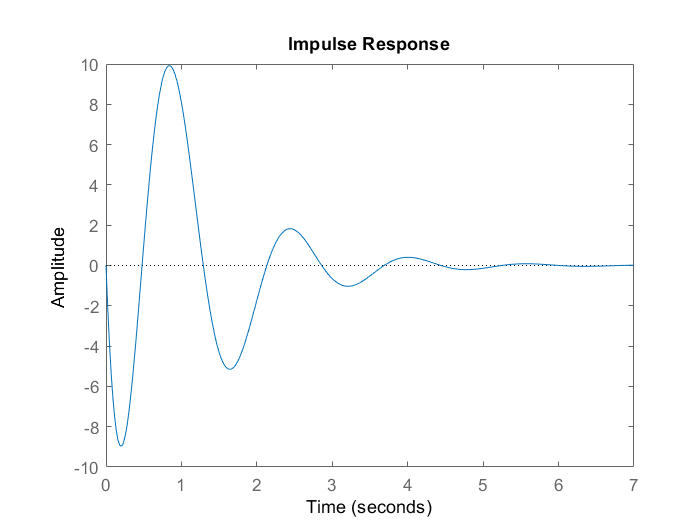

figure (1)
impulse(TFH); %plot the impulse reponse

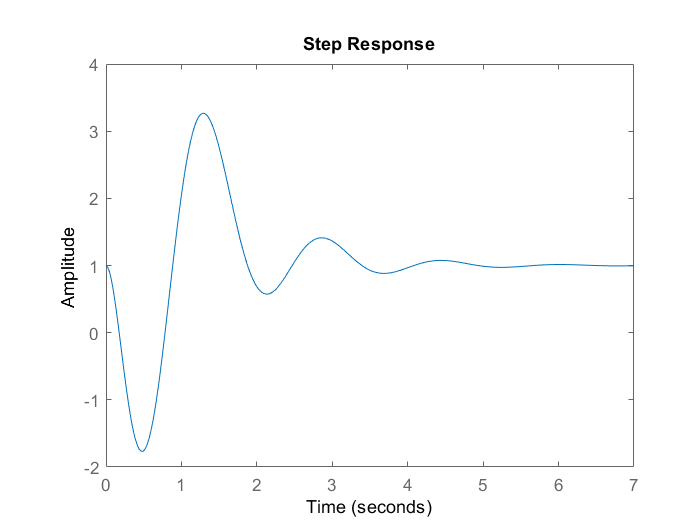

figure(2)
step(TFH)

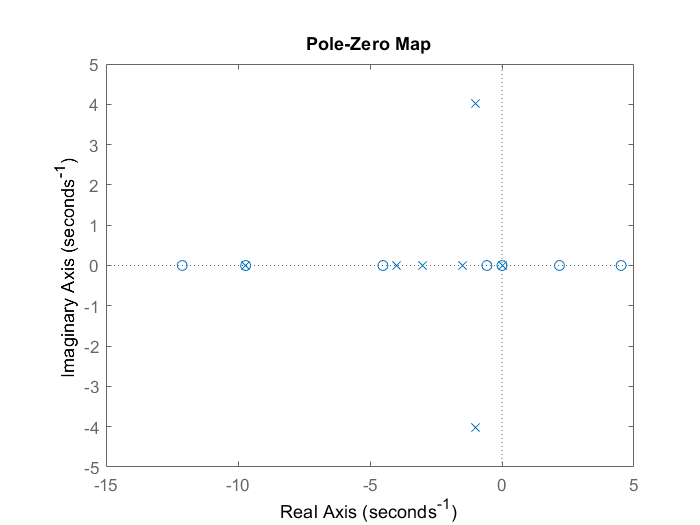

pzplot(TFH)